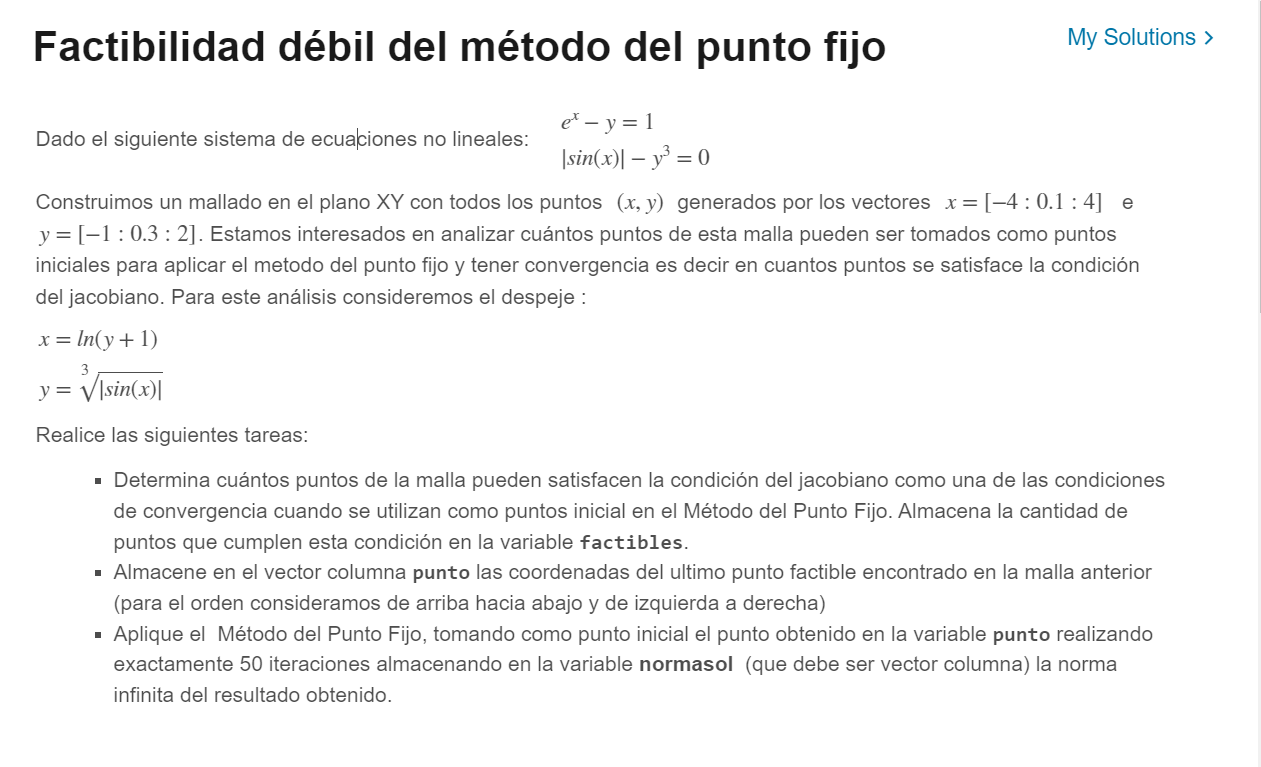

format long
syms x y
u = log(y+1);
v = nthroot(abs(sin(x)),3);
G = [u;v];
G = matlabFunction(G);

dG = jacobian(G(x,y),[x,y]);
dG_func = matlabFunction(dG);

factibles = 0;
for xi = -4:0.1:4
    for yi = -1:0.3:2
        M = double(dG_func(xi,yi));
        if norm(M,inf) < 1
            punto = [xi ; yi];
            factibles = factibles + 1;
        end
    end
end

function x1 = pfijos(g,x0,MaxIter)
    error = 1;
    for i = 1:MaxIter
        x1 = g(x0(1),x0(2));
        error = norm(x1-x0,inf)/norm(x1,inf);
        x0 = x1;
    end
end

punto

punto =      4
     2


factibles

factibles =    490



sol = pfijos(G,punto,50)

sol =    0.603098315752736
   0.827773054582335




normasol = norm(sol,inf)

normasol =    0.827773054582335
